clear;
clf;

% Post proscessing of FreeFem++ data in matlab.
% Claire R.A Curry

% Code to convert data output by FreeFem++ to matlab readable data
% Using the ffmatlib library
% https://github.com/samplemaker/freefem_matlab_octave_plot

filePrefix = {'t1r30','t1r60','t1r90', 't1r120', 't1r150'};

addpath('ffmatlib');
[p30,b30,t30]=ffreadmesh(strcat(filePrefix{1},'.msh'));
[p60,b60,t60]=ffreadmesh(strcat(filePrefix{2},'.msh'));
[p90,b90,t90]=ffreadmesh(strcat(filePrefix{3},'.msh'));
[p120,b120,t120]=ffreadmesh(strcat(filePrefix{4},'.msh'));
[p150,b150,t150]=ffreadmesh(strcat(filePrefix{5},'.msh'));
vh30=ffreaddata(strcat(filePrefix{1},'Vh.txt'));
vh60=ffreaddata(strcat(filePrefix{2},'Vh.txt'));
vh90=ffreaddata(strcat(filePrefix{3},'Vh.txt'));
vh120=ffreaddata(strcat(filePrefix{4},'Vh.txt'));
vh150=ffreaddata(strcat(filePrefix{5},'Vh.txt'));

totalFrames = 51

totalFrames = 51

for j = 0:totalFrames-1
    u30(:,j+1) = ffreaddata(sprintf('t1r30%i.txt', j));
    u60(:,j+1) = ffreaddata(sprintf('t1r60%i.txt', j));
    u90(:,j+1) = ffreaddata(sprintf('t1r90%i.txt', j));
    u120(:,j+1) = ffreaddata(sprintf('t1r120%i.txt', j));
    u150(:,j+1) = ffreaddata(sprintf('t1r150%i.txt', j));
end

% Interpolate the snapshot for points other than the triangulation points
% To compare with an equispaced grid generated by linspace(...)

x = linspace(0,1,100);
y = linspace(0,1,100);
[XX,YY] = meshgrid(x,y);

% Store interpolated data for each resolution
for i = 1:totalFrames
    U30(i,:) = ffinterpolate(p30,[],t30,vh30,x,y,u30(:,i))';
    U60(i,:) = ffinterpolate(p60,[],t60,vh60,x,y,u60(:,i))';
    U90(i,:) = ffinterpolate(p90,[],t90,vh90,x,y,u90(:,i))';
    U120(i,:) = ffinterpolate(p120,[],t120,vh120,x,y,u120(:,i))';
    U150(i,:) = ffinterpolate(p150,[],t150,vh150,x,y,u150(:,i))';
end

Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


% Max error plot data calculation

% How much time elapsed between each snap shot of the approximation
timeResolution = 0.1;
% Number of fourier terms
N = 100000;

% Initializnig arrays to hold data
maxEr30 = zeros(1,totalFrames);
maxEr60 = zeros(1,totalFrames);
maxEr90 = zeros(1,totalFrames);
maxEr120 = zeros(1,totalFrames);
maxEr150 = zeros(1,totalFrames);

% For each snapshot calculate and store the maximum error
% At each resolution
for i = 1:totalFrames

    uexact = test1Exact(x,(i-1)*timeResolution,N);

    maxEr30(i) = max(abs(uexact(2:end-1)-U30(i,2:end-1)));
    maxEr60(i) = max(abs(uexact(2:end-1)-U60(i,2:end-1)));
    maxEr90(i) = max(abs(uexact(2:end-1)-U90(i,2:end-1)));
    maxEr120(i) = max(abs(uexact(2:end-1)-U120(i,2:end-1)));
    maxEr150(i) = max(abs(uexact(2:end-1)-U150(i,2:end-1)));
end

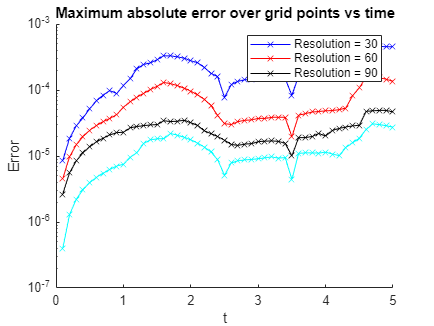

% Ploting Max Error vs Time
clf;

hold on

plot(0:0.1:5,maxEr30, Marker="x", color="b");
plot(0:0.1:5,maxEr60, Marker="x", color="r");
plot(0:0.1:5,maxEr90, Marker="x", color="k");
plot(0:0.1:5,maxEr120, Marker="x", color="c");
plot(0:0.1:5,maxEr150, Marker="x", color="g");

title("Maximum absolute error over grid points vs time");
legend( ...
    "Resolution = 30", ...
    "Resolution = 60", ...
    "Resolution = 90", ...
    "Resolution = 120", ...
    "Resolution = 150");
xlabel("t");
ylabel("Error");
yscale("log");

hold off

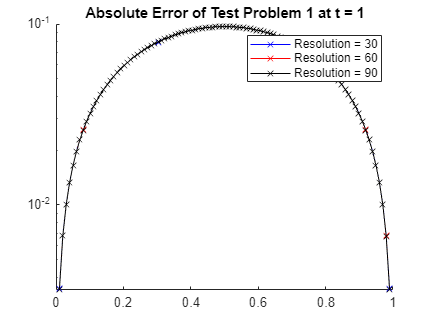

av1 = 1.1704e-04

av2 = 5.4842e-05

av3 = 2.2917e-05

ans = 1.0e-03 *

    0.0779    0.0566    0.0147    0.0328    0.0424    0.0239    0.0520    0.0088    0.0410    0.0047    0.0306    0.0215    0.0067    0.0375    0.0059    0.0524    0.0697    0.0056    0.0437    0.0548    0.0383    0.0154    0.1163    0.1161    0.0741    0.0953    0.0054    0.0630    0.0421    0.0387    0.0137    0.0777    0.0398    0.0350    0.0998    0.0238    0.0065    0.0381    0.0184    0.0796    0.0232    0.0412    0.0788    0.0307    0.0094    0.0464    0.0967    0.0756    0.0419    0.0399


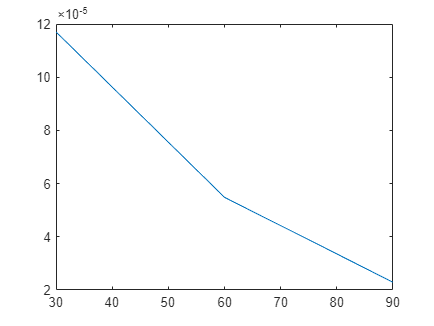

% Plot error at a particular time t
clf

% Number of equispace grid points
resolution = 100;
% Number of fourier terms for exact solution calculations
N = 100000;
% Generate grid points
x = linspace(0,1,resolution);
% Generate exact data on x grid points for time t with N fourier terms
uexact = test1Exact(x,1,N);

% Plotting code, removing boundary points.
hold on

    plot(x(2:end-1),abs(uexact(2:end-1)-U30(11,2:end-1)), Marker="x", color="b");
    plot(x(2:end-1),abs(uexact(2:end-1)-U60(11,2:end-1)), Marker="x", color="r");
    plot(x(2:end-1),abs(uexact(2:end-1)-U90(11,2:end-1)), Marker="x", color="k");
    plot(x(2:end-1),abs(uexact(2:end-1)-U120(11,2:end-1)), Marker="x", color="c");
    plot(x(2:end-1),abs(uexact(2:end-1)-U120(11,2:end-1)), Marker="x", color="g");

    title("Absolute Error of Test Problem 1 at t = 1");
    legend( ...
        "Resolution = 30", ...
        "Resolution = 60", ...
        "Resolution = 90", ...
        "Resolution = 120", ...
        "Resolution = 150");
    yscale("log")

hold off

% Helper function to calculate exact solution values
% at (x,t) with N fourier terms.
function u = test1Exact(x,t,N)
    
    % Exact solution as anonymous function
    phi = @(x,tau,N) 2*(((-1)^(N+1)+1)/(pi*N*(pi^2*N^2-1)))* ...
        (sin(tau)-1/(pi*N)*sin(N*pi*t))*sin(N*pi*x);

    numt = length(t);
    u=zeros(numt,length(x));
    for ti = 1:numt
        for n=1:N
            u(ti,:) = u(ti,:) + phi(x,t(ti),n);
        end
    end
end
